# Matlab notes - Intro to Matlab

## Getting help

doc sin
% Getting help on a general topic
doc volatility


## Simulate flip of a coin

if rand<.5 % rand by itself will generate between 0-1
    disp('heads'); % disp to show strings
else 
    disp('tails');
end

tails


## Variables

my_pi = 3.14

my_pi = 3.1400

my_char = "hello world"

my_char = "hello world"


pi % some vars are already set in matlab like i,j,pi,Inf,NaN

ans = 3.1416


% end a line with a semicolon to suppress output
% typically don't want to write to the screen
% runs very slowly
my_pi2 = 3.141;

## Arrays

Matlab uses normal matrix of numbers, and cell array of objects (list columns from R)

% row vector
row = [1 2 5.4 -6]

row =     1.0000    2.0000    5.4000   -6.0000



% col vector
col = [1; 2; 4]

col =      1
     2
     4



% size and length
size(col)

ans =      3     1


[r,c] = size(col) % destructuring assignment

r = 3

c = 1

length(col)

ans = 3

## Matrices

a = [1 2];
b = [3 4];
c = [5;6];

% Matrix from concatenation
d = [a;b] % a is the first row, b is the second row

d =      1     2
     3     4


e = [a b] % concat them all into 1 row

e =      1     2     3     4


## Save and load

% save myFile a b
% saves as a .mat file

x = 4;
clear('x') % or just clear x

% load to get it back in

## Basic arithmetic

7/45

ans = 0.1556

4^2

ans = 16

## Clear command window

clc

## Built in functions

Transpose!

a = [1 3 4 5];
transpose(a)

ans =      1
     3
     4
     5


a'

ans =      1
     3
     4
     5


## Operations - basic

row = [1 3 4]

row =      1     3     4


col = [2;5;6]

col =      2
     5
     6



c = row' + col

c =      3
     8
    10


d = row + col'

d =      3     8    10


## Operators - element wise VS normal matrix rules

By default, matlab does normal matrix rule with /, *, ^

To make it work element by element, use a period before the operation! ./ and .* and .^

a = [1 2 3];
b = [4;2;1];

a * b % normal matrix rules

ans = 11

a .* b % outer product

ans =      4     8    12
     2     4     6
     1     2     3



% / this does multiply by inverse, but you might want to just do it

## Initialize a vector

one = ones(2,10) % 2 rows, 10 columns, all 1

one =      1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1



zero = zeros(1,8)

zero =      0     0     0     0     0     0     0     0


r = rand(1,45)

r =     0.4898    0.4456    0.6463    0.7094    0.7547    0.2760    0.6797    0.6551    0.1626    0.1190    0.4984    0.9597    0.3404    0.5853    0.2238    0.7513    0.2551    0.5060    0.6991    0.8909    0.9593    0.5472    0.1386    0.1493    0.2575    0.8407    0.2543    0.8143    0.2435    0.9293    0.3500    0.1966    0.2511    0.6160    0.4733    0.3517    0.8308    0.5853    0.5497    0.9172    0.2858    0.7572    0.7537    0.3804    0.5678



n = nan(1, 5) % useful to show if any step in the code has changed the value of a variable

n =    NaN   NaN   NaN   NaN   NaN


## Array subsetting

a = [1 2 3];
b = [4;2;1];

% first element
a(1)

ans = 1


% first 2 elements
b(1:2)

ans =      4
     2



% 1 through the end
a(1:end)

ans =      1     2     3



% last two
a(end-1:end)

ans =      2     3


Matrix indexing

c = a .* b

c =      4     8    12
     2     4     6
     1     2     3


c(1,1) % grab the exact position

ans = 4


c(4) % linear indexing, goes down the column

ans = 8


c(1,1:end)

ans =      4     8    12



% the colon here allows me to select all columns!
c(1, :) 

ans =      4     8    12



% second column of c
c(:, 2) 

ans =      8
     4
     2



% replace the first row with a vector
c(1, :) = [5 6 7] 

c =      5     6     7
     2     4     6
     1     2     3


## Advanced indexing

vec = [5 3 1 9 7];

% min/max
minval = min(vec)

minval = 1


[minval,minlocation] = min(vec)

minval = 1

minlocation = 3


% filtering for certain rows
subset = vec(find(vec == 5))

subset = 5

## Plotting

x = linspace(0,4*pi,10) % from 0 to 4pi, get 10 equally spaced values

x =          0    1.3963    2.7925    4.1888    5.5851    6.9813    8.3776    9.7738   11.1701   12.5664


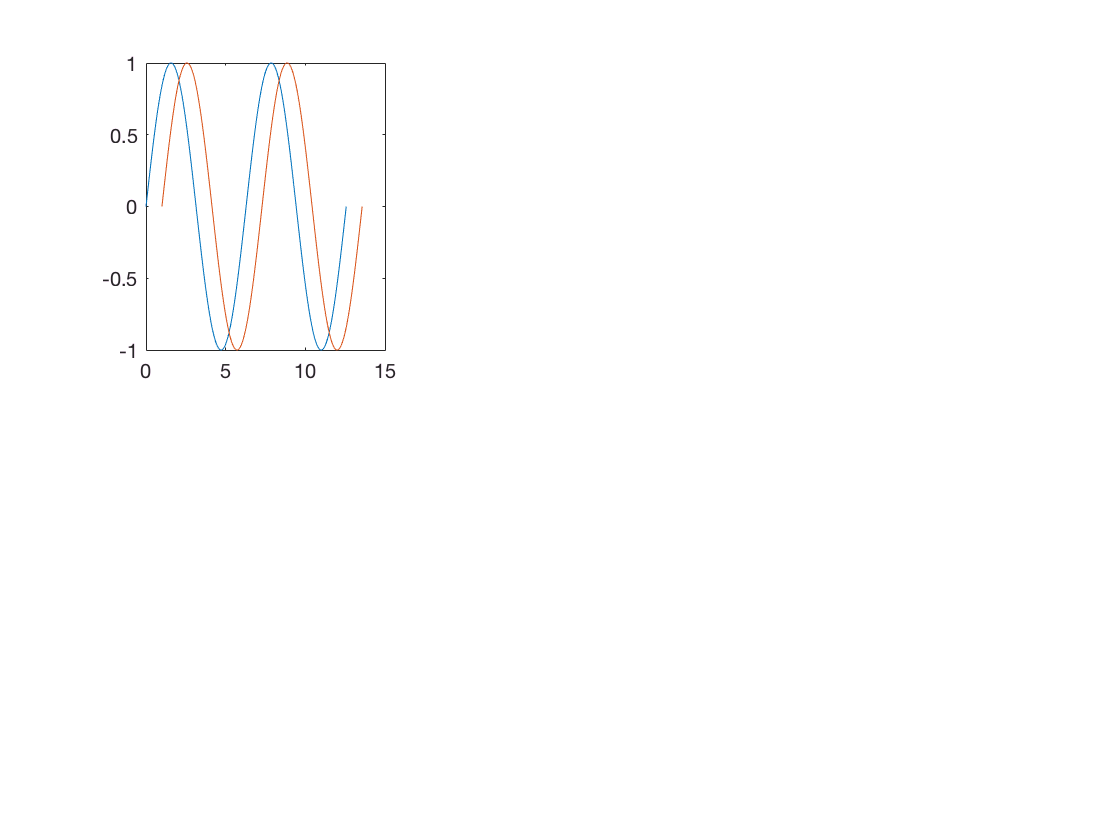

plot(x, sin(x)) % plot it

y = linspace(0, 4*pi, 1000);
plot(y, sin(y))
plot(y, sin(y), y+1, sin(y))

% doc plot

% subplots
% subplot(2, 3, 1) % figure with 2 rows 3 columns and activate spot 1
% doc subplot

## User defined functions

% only the avg is returned
stats([1 2 3])

ans = 2


% must explicitly assign them all to see them all
[avg, sd, range] = stats([1 2 3]) 

avg = 2

sd = 1

range =      1     3


## Overloading

This is the process of having different function signatures

a = fun(x)

[a, b] = fun(x)

a = fun(x,y)

varargin, nargin, varargout, nargout to do this. see the help for them

## Flow control

% why the hell is not equal this?
% ~=

x=4;
y=5;
x ~= y

ans = logical
   1



% Useful other ones might be `any` and `all`!!!
x = [4 5 6]

x =      4     5     6


any(x == 4)

ans = logical
   1


all(x < 7)

ans = logical
   1


if statements work with if, elseif, else, end

for and while loops work too

## Random numbers

rand % uniform distr

ans = 0.6068


randn % draw from gaussian normal

ans = 1.1909


rand('state', 0); % set the random seed
rand(1)

ans = 0.9501

rand(1)

ans = 0.2311


% random can give tons of different distributions of random numbers
% doc random

% shifting
% In general, you can generate N random numbers in the interval (a,b) with the formula r = a + (b-a).*rand(N,1).
% (1 -> 2)
r = 1 + (2 - 1) * rand(2, 1)

r =     1.6068
    1.4860


## Histograms

Brownian motion

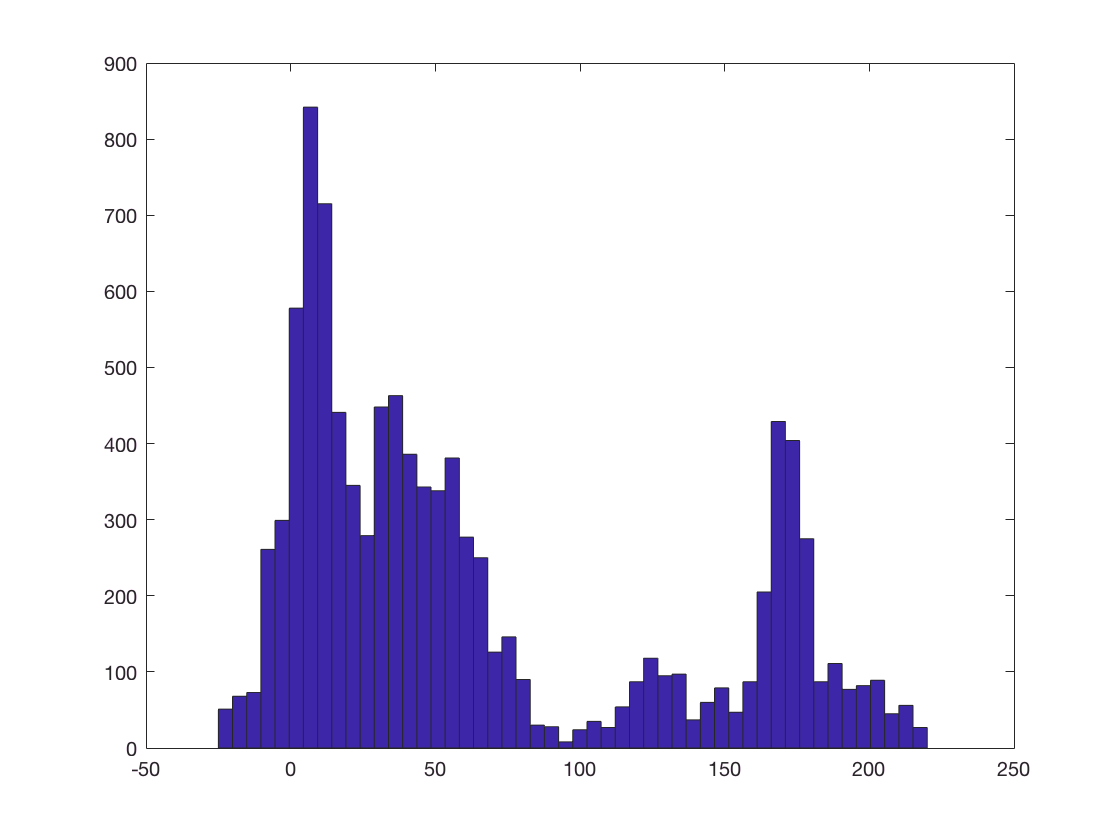

x = zeros(10000, 1);
for n = 2:10000
    if rand < 0.5
        x(n) = x(n-1) - 1;
    else
        x(n) = x(n-1) + 1;
    end
end

figure;
hist(x, 50)

## Importing data

% importdata function
% xlsread
%{
num = xlsread(filename)
num = xlsread(filename,sheet)
num = xlsread(filename,xlRange)
num = xlsread(filename,sheet,xlRange)
num = xlsread(filename,sheet,xlRange,'basic')
[num,txt,raw] = xlsread(___)
%}
% doc xlsread

% xlswrite

## UDF example

The user defined function has to be placed after the call to it for some reason

function [avg, sd, range] = stats(x) 
    avg   = mean(x);
    sd    = std(x);
    range = [min(x) max(x)];
end